# first order measured

% fmfile3='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Milestone 2 Data.txt';
% fmfileID3=fopen(fmfile3);
% fmtextstuff3=textscan(fmfileID3, '%s %s %s %s','Delimiter','\t');
% fclose(fmfileID3);
% 
% fmtime3=string(fmtextstuff3{1,3});
% fmtime3=erase(fmtime3,'4/22/2022  14:14:');
% fmvolt3=string(fmtextstuff3{1,4});
% 
% fmtime3=fmtime3(5:1005);
% fmvolt3=fmvolt3(5:1005);
% 
% fmtime3=str2double(fmtime3);
% fmvolt3=str2double(fmvolt3);
% 
% fmtime3=fmtime3-fmtime3(1);
% fmvolt3=fmvolt3-fmvolt3(1);

## second order measured

smfile3='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Milestone 2 Data.txt';
smfileID3=fopen(smfile3);
smtextstuff3=textscan(smfileID3,'%s %s %s %s','Delimiter','\t');
fclose(smfileID3);

smtime3=string(smtextstuff3{1,3});
smtime3=erase(smtime3,'4/22/2022  14:14:');
smvolt3=string(smtextstuff3{1,4});

smtime3=smtime3(240:600);
smvolt3=smvolt3(240:600);

smtime3=str2double(smtime3);
smvolt3=str2double(smvolt3);

smtime3=smtime3-smtime3(1);
smvolt3=smvolt3-smvolt3(1);

## second order simulated

ssfile3='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Time Domain.csv';
ssdata3=readmatrix(ssfile3);

sstime3=ssdata3(:,1);
ssvolt3=ssdata3(:,2);

## plot

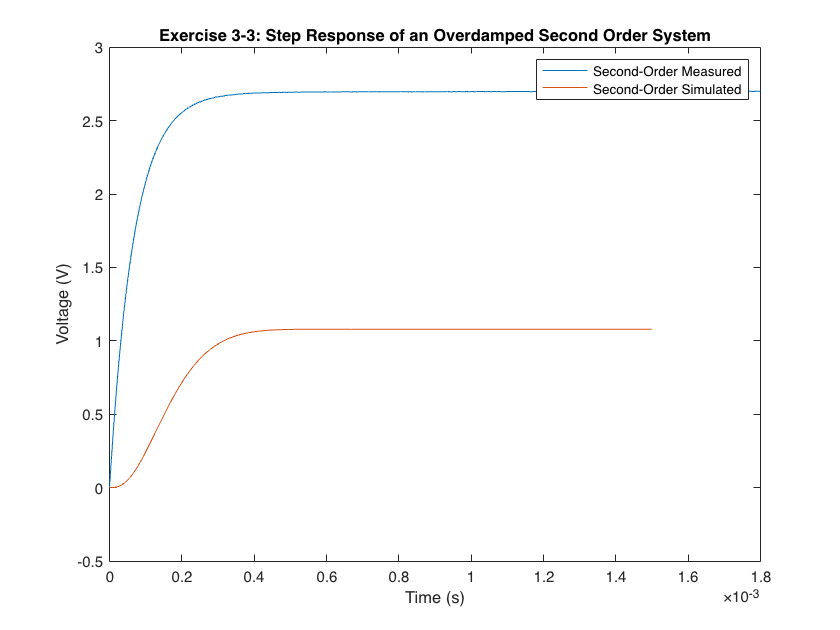

% plot(fmtime3,fmvolt3,'DisplayName','First-Order Measured');
% hold on
plot(smtime3,smvolt3,'DisplayName','Second-Order Measured');
hold on
plot(sstime3,ssvolt3,'DisplayName','Second-Order Simulated');
hold on 

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Exercise 3-3: Step Response of an Overdamped Second Order System');
legend 
hold off